# Pràctica 7. Exercici 2

Exercici 5 del document CN_full5.pdf

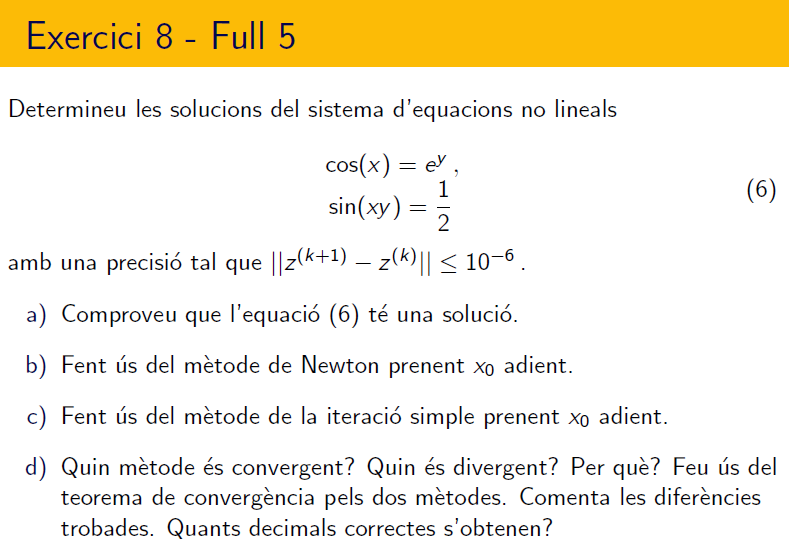

================================================================================

- `Comproveu que el sistema d'equacions té una solució`

F1 = @(x,y) exp(y)-cos(x)

F1 = function_handle with value:
    @(x,y)exp(y)-cos(x)


F2 = @(x,y) 0.5 - sin(x*y)

F2 = function_handle with value:
    @(x,y)0.5-sin(x*y)



fimplicit(F1,[-5 5 -5 5],':r','LineWidth',2)
hold on
fimplicit(F2,[-5 5 -5 5],'--g','LineWidth',2),grid minor

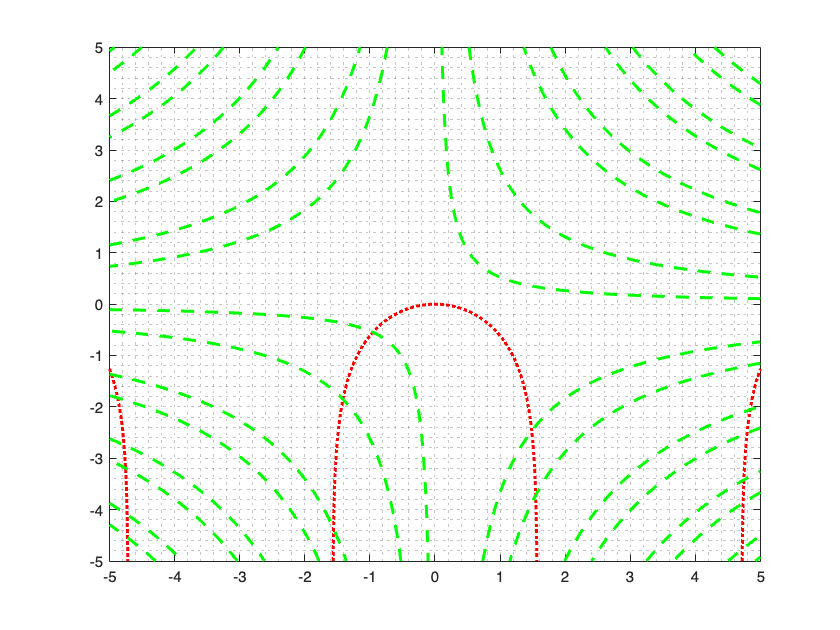

hold off


clearvars
options = optimoptions('fsolve','Display','iter','StepTolerance',5e-15,'OptimalityTolerance',5e-15);
x0 = [-1.5;-1.8];
[x, fval] = fsolve(@myfun,x0,options)

F =         0.0945616865538836


F =         0.0945616865538836        0.0726201197661702


F =          0.094561708849634


F =          0.094561708849634        0.0726201561398271


F =          0.094561682120222


F =          0.094561682120222        0.0726201561398271



                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3       0.0142156                         0.213               1


F =       0.000576814872951414


F =       0.000576814872951414      -0.00230398720914171


F =       0.000576835676129678


F =       0.000576835676129678      -0.00230395351085366


F =       0.000576810538812728


F =       0.000576810538812728      -0.00230395351085366


     1          6     5.64107e-06       0.100002        0.00312               1


F =       3.81938727311848e-07


F =       3.81938727311848e-07      1.33405593888414e-06


F =       4.02737670907038e-07


F =       4.02737670907038e-07      1.36784063498041e-06


F =       3.77608956408926e-07


F =       3.77608956408926e-07      1.36784063498041e-06


     2          9     1.92558e-12     0.00220522       2.52e-06               1


F =       3.61932706027801e-14


F =       3.61932706027801e-14      7.98472399310413e-13


F =       2.07989714617884e-08


F =       2.07989714617884e-08      3.37854448861918e-08


F =      -4.32973565334116e-09


F =      -4.32973565334116e-09      3.37854444976138e-08


     3         12     6.38868e-25    6.69053e-07       1.32e-12               1

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>


x =          -1.41328778776395
         -1.85241385417651


fval =       3.61932706027801e-14      7.98472399310413e-13


- `Calculeu iterats pel mètode de Newton, prenent x0 adient fins que `$$\vert\vert
	\mathbf{Z}^{(k+1)}-\mathbf{Z}^{(k)}\vert\vert\le 10^{-6}\,, $$  per $Z = [x,y]^t$

format longG
x0 = [-1.5;-1.8]; %escullo una x0 que estigui dins d'un interval proper a l'arrel
[x, fval] = fsolve(@myfun,x0)   

F =         0.0945616865538836


F =         0.0945616865538836        0.0726201197661702


F =          0.094561708849634


F =          0.094561708849634        0.0726201561398271


F =          0.094561682120222


F =          0.094561682120222        0.0726201561398271


F =       0.000576814872951414


F =       0.000576814872951414      -0.00230398720914171


F =       0.000576835676129678


F =       0.000576835676129678      -0.00230395351085366


F =       0.000576810538812728


F =       0.000576810538812728      -0.00230395351085366


F =       3.81938727311848e-07


F =       3.81938727311848e-07      1.33405593888414e-06


F =       4.02737670907038e-07


F =       4.02737670907038e-07      1.36784063498041e-06


F =       3.77608956408926e-07


F =       3.77608956408926e-07      1.36784063498041e-06


F =       3.61932706027801e-14


F =       3.61932706027801e-14      7.98472399310413e-13


F =       2.07989714617884e-08


F =       2.07989714617884e-08      3.37854448861918e-08


F =      -4.32973565334116e-09


F =      -4.32973565334116e-09      3.37854444976138e-08



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =          -1.41328778776395
         -1.85241385417651


fval =       3.61932706027801e-14      7.98472399310413e-13


myfun(x);

F =       3.61932706027801e-14


F =       3.61932706027801e-14      7.98472399310413e-13


valorBo = x;

F  = @(x,y)[exp(y)-cos(x); 0.5 - sin(x*y)];
F(x0(1),x0(2));
JF = @(x,y)[sin(x),exp(y); -y*cos(y*x), -x*cos(x*y)];
for k=1:5
    y  = linsolve(JF(x0(1),x0(2)),(-F(x0(1),x0(2))));
    x0 = x0+y;
    decimalsCorrectes = min(abs(valorBo'-x0'));

    res(k).y = y;
    res(k).x0 = x0;
    res(k).decimalsCorrectes = decimalsCorrectes;
end

res

res = 1×5 struct array with fields:
    y
    x0
    decimalsCorrectes



F(x0(1),x0(2));

tolF = norm(F(x0(1),x0(2)),'inf'); %aqui hauries de posar 10^(-6)
tolX = norm(y,'inf');
disp(['Solució = ',num2str(x0')])

Solució = -1.4133     -1.8524


disp(['tolF = ',num2str(tolF)])

tolF = 5.5511e-17


disp(['tolX = ',num2str(tolX)])

tolX = 6.8028e-17


disp(['Iteracions = ',num2str(k)])

Iteracions = 5



%Obtinc 12 decimals correctes

- `Calculeu iterats pel mètode de l'iteració simple, prenent x0 adient fins que `$$\vert\vert
	\mathbf{Z}^{(k+1)}-\mathbf{Z}^{(k)}\vert\vert\le 10^{-6}\,, $$ per $Z = [x,y]^t$

format longG;
G1 = @(x,y)exp(y)

G1 = function_handle with value:
    @(x,y)exp(y)


G2 = @(x,y)0.5;
%JG = @(x,y)[0,-2*y; -1-y^2, -2*x*y+10]; %es la jacobiana
x0 = [-1.5;-1.8];
%norm(JG(x0(1),x0(2)),1); %podria ser norma 2
%norm(JG(x0(1),x0(2)),'inf');
for k=1:5
    x0(1) = G1(x0(1),x0(2));
    x0(2) = G2(x0(1),x0(2));
    disp([k,x0']);
end

                         1         0.165298888221587                       0.5

                         2          1.64872127070013                       0.5

                         3          1.64872127070013                       0.5

                         4          1.64872127070013                       0.5

                         5          1.64872127070013                       0.5




%F = @(x,y)[x^2-10*x + y^2 + 8; x*y^2 + x - 10*y + 8];

tolF = norm(F(x0(1),x0(2)),'inf');

disp(['Solució = ',num2str(x0')])

Solució = 1.6487         0.5


disp(['tolF = ',num2str(tolF)])

tolF = 1.7266


disp(['Iteracions = ',num2str(k)])

Iteracions = 5



%No obtenim cap decimal correcte, és un mètode divergent a partir del punt

- `Compareu els resultats obtinguts amb el resultat de fsolve de MATLAB®. Quants decimals correctes s'obtenen? `

function F = myfun(x)  
    F(1) = exp(x(2)) - cos(x(1)) 
    F(2) = 0.5 - sin(x(1)*x(2))
end